# Ejercicio 1: modelo muelle - amortiguador

m = 1;
b = 1;
k = 10;

# Ejercicio 3.a: halla el sistema equivalente

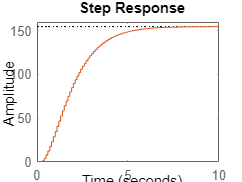

t = 0.1;

z = tf('z',t);

G = 1.5*(z - 0.51)/((z - 0.9)^2 * (z - 0.5) * (z - 0.05));

%Eliminacion de par polo - cero

Origen1 = (1 + 0.51)/(1 + 0.50);

Par1 = (0.9 + 0.51)/(0.9 + 0.50);
Par2 = (0.05 + 0.51)/(0.05 + 0.50);

%Comprobar si el error es menor de 0.10
abs(Par1 - Origen1);
abs(Par2 - Origen1);



%Eliminacion de polo rapido
Origen2 = 1/(1 + 0.005) * (1/0.9);

Polo1 = 1/(0.9 + 0.005);

%Comprobar si el error es menor de 0.10
abs(Polo1 - Origen2);



%Obtencion de la ganancia
Gred = 1/((z - 0.9)^2*z);

%La ganancia sera KG/Kred
KG = abs(evalfr(G,1));
Kred = abs(evalfr(Gred,1));

%Por lo tanto, la funcion de transferencia reducida sera:
Gred = Gred * (KG/Kred);

%Imprimir la entrada para comprobar que las dos salidas son iguales
step(G,Gred)

# Ejercicio 3.b: control con un regulador proporcional

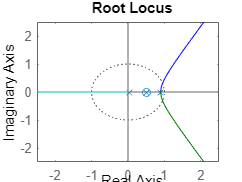

%Pregunta 1: representacion de LDR
rlocus(G)            %Representacion del lugar de las raices



%Pregunta 2: analisis de estabilidad del sistema. Obtencion de K critica
[R, K] = rlocus(G,[0.01:0.001:0.07]);  %Matriz de polos para valores de K

modulo = zeros(4,56);%Reservar en memoria

for iter = 1:1:length(K)
    modulo(:,iter) = abs(R(:,iter));
    if (max(modulo(:,iter) )>= 1)               %IMPORTANTE!!! Analizar comprobando el valor maximo de cada columna
        sprintf("El valor de K es: %f", K(iter))
        break
    end
end

ans = "El valor de K es: 0.064000"

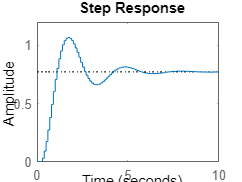


step(feedback(G*0.022,1))              %Respuesta estable

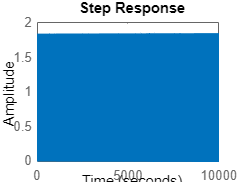

step(feedback(G*0.0639382,1))          %Respuesta criticamente estable

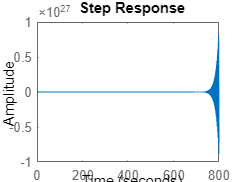

step(feedback(G*0.07,1))               %Respuesta inestable

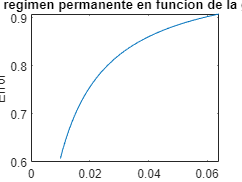


%Pregunta 3: analisis del error en regimen permanente

for iter2 = 1:1:iter
    error(iter2) = abs(evalfr(feedback(G*K(iter2),1),1));   %Calculamos el error del sistema en lazo cerrado hasta K critica
end

plot(K(1:iter),error)                           %Representar el valor del error frente a K
title('Variacion del error en regimen permanente en funcion de la ganancia del regulador');
xlabel('Ganancia Kp');
ylabel('Error');

# Ejercicio 3.c: simulacion de un motor de cc

%Requerimientos de diseño
Ns = 20;
Np = 15;


%Obtencion de los polos que dan la respuesta deseada
wd = pi/Np;
sigma = pi/Ns;
P1 = exp(-sigma) * cos(wd) + exp(-sigma) * sin(wd) * 1i    

P1 = 0.8360 + 0.1777i

P2 = exp(-sigma) * cos(wd) - exp(-sigma) * sin(wd) * 1i

P2 = 0.8360 - 0.1777i

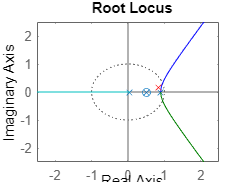


%Representacion de la respuesta deseada
rlocus(G)
hold on
plot(real(P1),imag(P1),'xr')            

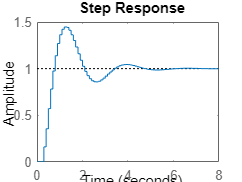


%Como la respuesta no pasa por LDR, añadir un derivador
Angcero = pi + angle(evalfr(1/G*z,P1));         %Criterio del argumento
x = sym('x');
eq = Angcero == atan(imag(P1)/(real(P1) - x));  %Criterio del modulo
a = double(solve(eq));

Reg1 = (z - a)/z;                      %Regulador PD para que la respuesta pase por RLOCUS
Reg2 = Reg1 * (z - 0.90)/(z - 1);        %Regulador PID para error 0

K = abs(evalfr(1/(G*Reg2),P1));         %Ganancia total

Reg2 = K*Reg2;
figure
step(feedback(Reg2*G,1))               %Se sacrifica un poco de sobreoscilacion para que la respuesta se de en el tiempo deseado

# Ejercicio 3.c: parametros simulink

%Constantes del motor
K = 20;
L = 0.2;
R = 6;
Kp = 10;
Kb = 0.1;
J = 17;
B = 5;

T = 0.1;                              %Tiempo de muestreo indicado en el enunciado
%Cargar identification data: load('R:\Regulacion\Practica 2\IdentificationData.mat')

%Pregunta 1: Escalon
numc = 6.3;                           %Valor al que tiende salida identification data en escalon
denc = [3.1 1];                       %Tiempo para alcanzar el 63%
G1d = c2d(tf(numc,denc),T);           %Discretizacion de la funcion en continuo
[num,den] = tfdata(G1d);              %Extraccion del numerador y el denominador en discreto
num1 = cell2mat(num);                 %Numerador discreto
den1 = cell2mat(den);                 %Denominador discreto

%Pregunta 2: Impulso
numImp = 7.44;                        %Valor de K calculado
denImp = [4 1];                       %Valor Ts + 1 calculado
G2d = c2d(tf(numImp,denImp),T);       %Discretizacion
[numImpD,denImpD] = tfdata(G2d);      %Extraccion del num y den en discreto por separado
num2 = cell2mat(numImpD);             %Cast para usar en simulink
den2 = cell2mat(denImpD);             %Cast para usar en simulink

%Pregunta 3: PI para 10 segundos
R1 = 0.57*(z - 0.8) / (z - 1);
[numR1,denR1] = tfdata(R1);
numR1sim = cell2mat(numR1);        %Pasar a vector el numerador
denR1sim = cell2mat(denR1);        %Pasar a vector el denominador

%Pregunta 4: PI para 2 segundos
R2 = 4.2146*(z - 0.69) / (z - 1);
[numR2,denR2] = tfdata(R2);
numR2sim = cell2mat(numR2);        %Pasar a vector el numerador
denR2sim = cell2mat(denR2);        %Pasar a vector el denominador

%Pregunta 4.1.4
T2 = 0.01;
G1d_2 = c2d(tf(numc,denc),T2);
R3 = 2.61*(z - 0.8)/(z - 1);
[numR3,denR3] = tfdata(R3);
numR3sim = cell2mat(numR3);
denR3sim = cell2mat(denR3);

%Pregunta 4.1.7
R4 = 0.33*(z - 0.8)*(z - 1) / (z*(z + 1));
[numR4,denR4] = tfdata(R4);
numR4sim = cell2mat(numR4);        %Pasar a vector el numerador
denR4sim = cell2mat(denR4);        %Pasar a vector el denominador